# Laboratorio di Automatica (prova del 19 Giugno 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

June 19, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri il sistema di controllo di posizione di un motore elettrico in corrente continua mostrato in Fig. 1, dove 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


è la funzione di trasferimento del motore, da ingresso in tensione $u\;[\mathrm{V}]$ ad uscita in posizione $y\;[\mathrm{rad}]$, mentre


$$C(s)\,=\,\frac{U(s)}{E(s)}\,=\, \frac{s^2 + 2 \delta_z \omega_0\,s + \omega_0^2}{s^2 + \omega_0^2} \qquad\quad\text{con}\qquad\quad \delta_z=0.9\,,\qquad\omega_0= 2 \pi$$
  

è la funzione di trasferimento del controllore di posizione, con ingresso l'errore di posizione $e\,[\mathrm{rad}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

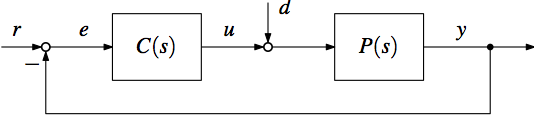

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Calcolare la funzione di trasferimento $T(s)$ del sistema in catena chiusa, dal riferimento $r$all'uscita $y$. Valutare successivamente la risposta$y$ e l'errore di inseguimento $e$ del sistema in catena chiusa ad un riferimento di posizione sinusoidale $r = \sin(\omega_0 t)$, su un intervallo temporale di $15\mathrm{s}$ (suggerimento: si usi la routine `lsim` per calcolare la risposta), e riportare i risultati in due grafici distinti.

Il sistema è in grado di garantire inseguimento perfetto a regime del riferimento ? Motivare la riposta.

*Soluzione*.

Calcolo della funzione di trasferimento in catena chiusa $T(s)$:

%   plant parmas
Tm = 0.03;
km = 5.2;
mu = 1;

%   plant tf
sysP = tf(km, [Tm, 1, 0]);

%   controller params
w0 = 2*pi*1;
dz = 0.9;

%   controller tf
sysC = tf([1, 2*dz*w0, w0^2], [1, 0, w0^2]);

%   loop tf
sysL = sysC*sysP;

%   closed-loop tf (r to y)
sysT = feedback(sysL, 1);
zpk(sysT)


ans =
 
        173.33 (s^2 + 11.31s + 39.48)
  -----------------------------------------
  (s+29.62) (s+2.32) (s^2 + 1.394s + 99.58)
 
Continuous-time zero/pole/gain model.



Determinazione della risposta in catena chiusa al riferimento sinusoidale:

%   closed-loop response
t = linspace(0, 15, 1500);
r = sin(w0*t);
y = lsim(sysT, r, t).';
e = r - y;

Visualizzazione della risposta $y$ e dell'errore di inseguimento $e$:

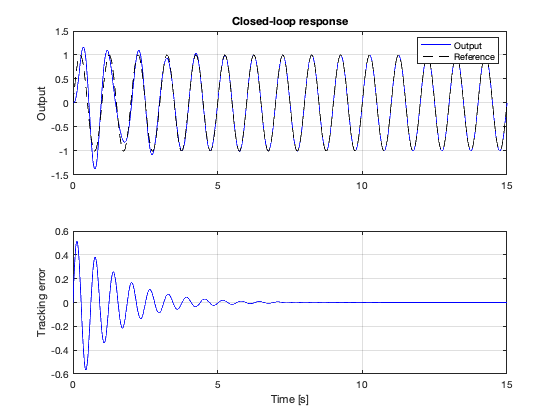

%   plot response
figure;
subplot(2,1,1);
plot(t, y, 'b');
hold on;
plot(t, r, 'k--');
ylabel('Output');
grid on;
legend('Output', 'Reference');
title('Closed-loop response');

subplot(2,1,2);
plot(t, e, 'b');
ylabel('Tracking error');
xlabel('Time [s]');
grid on;

Per il principio del modello interno, dato che la funzione di trasferimeto d'anello (in particolare, il controllore) contiene il modello del segnale di riferimento da inseguire (ovvero $\omega_0^2/(s^2+\omega_0^2)$, che è la Laplace transformata del segnale sinusoidale), l'inseguimento a regime del riferimento è perfettto, ovvero con errore di inseguimento nullo.

2) Calcolare la funzione di trasferimento $T_d(s)$del sistema in catena chiusa, dal disturbo $d$ all'uscita $y$. Valutare successivamente la risposta$y$ del sistema  in catena chiusa ad un disturbo sinusoidale $d(t) = 5 \sin(\omega_0 t)$, su un intervallo temporale di $15\mathrm{s}$, e riportare i risultati in un grafico.

Il sistema è in grado di garantire reiezione perfetta a regime del disturbo ? Motivare la riposta.

*Soluzione*.

Calcolo della funzione di trasferimento $T_d(s)$:

%   closed-loop response (d to y)
sysPS = feedback(sysP, sysC);
zpk(sysPS)


ans =
 
            173.33 (s^2 + 39.48)
  -----------------------------------------
  (s+29.62) (s+2.32) (s^2 + 1.394s + 99.58)
 
Continuous-time zero/pole/gain model.



Determinazione della risposta al disturbo sinusoidale:

%   closed-loop sinusoidal disturbance rejection
t = linspace(0, 15, 1500);
d1 = 5*sin(w0*t);
y1 = lsim(sysPS, d1, t).';

Visualizzazione della risposta $y$:

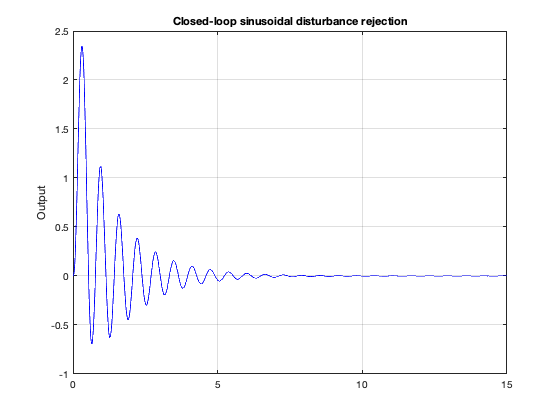

%   plot response
figure;
plot(t, y1, 'b');
ylabel('Output');
grid on;
title('Closed-loop sinusoidal disturbance rejection');

Dato che la funzione di trasferimento del controllore contiene il modello del disturbo sinusoidale agente all'ingresso dell'impianto, la reiezione del disturbo è perfetta.

3) Ripetere il punto 2, considerando ora un disturbo a gradino di ampiezza pari a $5V$.

Il sistema è in grado di garantire reiezione perfetta a regime del disturbo ? Motivare la riposta.

*Soluzione*.

Determinazione della risposta al disturbo a gradino:

%   closed-loop sinusoidal disturbance rejection
y2 = 5*step(sysPS, t).';

Visualizzazione della risposta $y$:

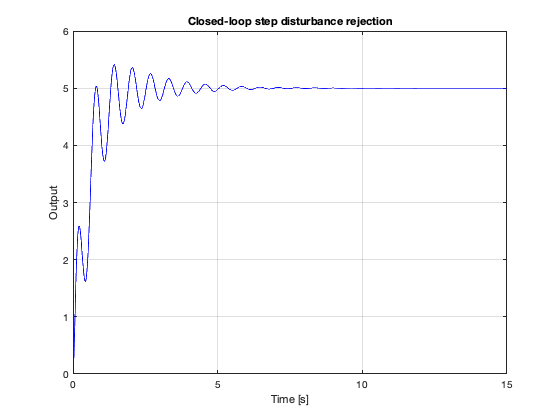

%   plot response
figure;
plot(t, y2, 'b');
ylabel('Output');
xlabel('Time [s]');
title('Closed-loop step disturbance rejection');
grid on;

Dato che la funzione di trasferimento del controllore non contiene l'azione integrale (ovvero non contiene il modello del disturbo costante da cancellare), la reiezione del disturbo non è perfetta.